# **Constellation operation research - GS to SAT**

**UT Austin CDUS**

**Hongseok Kim**

savepath = '/Users/hongseokkim/Desktop/Redstone_MILP/RS_MILP_07_GS_to_SAT';

number_of_satellites = 48;
number_of_orbit_planes = 12;
sim_duration = 1;
inclination_angle = 98;
FOV_value = 60;
Min_Elevation_angle = 15;

% Pilot Satellite Scinario - Input OM generation
sat_per_orbit_plane = number_of_satellites/number_of_orbit_planes;
orbit_altitude = 500; % 궤도 고도 (km)
orbit_radius = (6378 + orbit_altitude) * 1000; % 궤도 반지름 (m): r                                  입력 2.1 위성 고도 (km)

OM_pilot_sat = [ones(number_of_orbit_planes,1) * orbit_radius, ...              % SMA
                ones(number_of_orbit_planes,1) * 0, ...                         % ecc
                ones(number_of_orbit_planes,1) * inclination_angle, ...         % inc
                (0:360/number_of_orbit_planes:360-360/number_of_orbit_planes)', ... % RAAN
                ones(number_of_orbit_planes,1) * 0, ...                         % AOP
                ones(number_of_orbit_planes,1) * 0];                             % TA

start_time = datetime(2030, 1, 1, 0, 0, 0); % 시뮬레이션 시작 시간 (년, 월, 일, 시, 분, 초)               입력 2.2 시뮬레이션 시작 시간
stop_time = start_time + seconds(10000); % 시뮬레이션 시간
sample_time = 1;             % seconds
sc_pilot = satelliteScenario(start_time, stop_time, sample_time); % 시나리오 생성
propagator_options = numericalPropagator(sc_pilot, GravitationalPotentialModel="oblate-ellipsoid", ODESolver="ode78"); % J2 섭동
orbit_propagator = "numerical"; %궤도 전파기: ("numerical", "SGP4", "SDP4", "two-body-keplerian")   입력 2.3 궤도전파기 (수정 불필요)
sat_pilots = satellite(sc_pilot, OM_pilot_sat(:,1), ...
                                 OM_pilot_sat(:,2), ...
                                 OM_pilot_sat(:,3), ...
                                 OM_pilot_sat(:,4), ...
                                 OM_pilot_sat(:,5), ...
                                 OM_pilot_sat(:,6),"OrbitPropagator",orbit_propagator);

sat_OM_input = zeros(number_of_satellites,6);

for orbit_plane_index = 1:number_of_orbit_planes
  sat_OM_input((orbit_plane_index-1)*sat_per_orbit_plane+1,:) = OM_pilot_sat(orbit_plane_index,:);  
  pilot_sat_om = orbitalElements(sat_pilots(orbit_plane_index));
  pilot_sat_period = pilot_sat_om.Period;

  for sat_index = 2:sat_per_orbit_plane
    [r,v] = states(sat_pilots(orbit_plane_index),start_time + seconds((sat_index-1)*pilot_sat_period/sat_per_orbit_plane));
    [a,e,i,RAAN,AOP,TA] = ijk2keplerian(r,v);
    sat_OM_input((orbit_plane_index-1)*sat_per_orbit_plane+sat_index,:) = [a,e,i,RAAN,AOP,TA];
  end
end

% Main
stop_time = start_time + days(sim_duration); % 시뮬레이션 시간
sample_time = 500;             % seconds                                                          입력 2.4 시뮬레이션 샘플시간 간격
sc = satelliteScenario(start_time, stop_time, sample_time); % 시나리오 생성
satellite_name = "SAT_";                                                                  % 입력 2.5 위성 이름
sat = satellite(sc,sat_OM_input(:,1), ...
                   sat_OM_input(:,2), ...
                   sat_OM_input(:,3), ...
                   sat_OM_input(:,4), ...
                   sat_OM_input(:,5), ...
                   sat_OM_input(:,6), ...
                  "OrbitPropagator",orbit_propagator, ...
                  "Name",satellite_name + (1:number_of_satellites)');


Payload_list = conicalSensor(sat, "MaxViewAngle", FOV_value, "Name", sat.Name);
fieldOfView(Payload_list, 'LineColor', 'g');



% ============================================================
% 54 Global Ground Station Data
% ============================================================

GS_Data = [
    {"Daejeon-1",        36.37, 127.36}
    % {"Daejeon-2",        36.37, 127.36}
    % {"Jeju-1",           33.29, 126.46}
    % {"KingSejong-1",    -62.22, -58.79}
    % {"Weno-1",            7.45, 151.85}

    {"Svalbard-1",       78.23,  15.39}
    % {"Svalbard-2",       78.23,  15.39}
    % {"Svalbard-3",       78.23,  15.39}
    % {"Svalbard-4",       78.23,  15.39}
    % {"Svalbard-5",       78.23,  15.39}

    {"TrollSat-1",      -72.01,   2.53}
    % {"TrollSat-2",      -72.01,   2.53}
    % {"TrollSat-3",      -72.01,   2.53}
    % {"TrollSat-4",      -72.01,   2.53}

    {"Tromso-1",         69.66,  18.94}
    % {"Tromso-2",         69.66,  18.94}
    % {"Tromso-3",         69.66,  18.94}

    {"Inuvik-1",         68.32,-133.54}
    % {"Inuvik-2",         68.32,-133.54}
    % {"Inuvik-3",         68.32,-133.54}

    {"Fairbanks-1",      64.80,-147.50}
    % {"Fairbanks-2",      64.80,-147.50}
    % {"Fairbanks-3",      64.80,-147.50}

    {"McMurdo-1",       -77.85, 166.67}
    % {"McMurdo-2",       -77.85, 166.67}

    {"PuntaArenas-1",   -52.93, -70.85}
    % {"PuntaArenas-2",   -52.93, -70.85}
    % {"PuntaArenas-3",   -52.93, -70.85}

    {"Awarua-1",        -46.51, 168.38}
    % {"Awarua-2",        -46.51, 168.38}
    % {"Awarua-3",        -46.51, 168.38}
    % 
    % {"AliceSprings-1",  -23.70, 133.88}
    % {"AliceSprings-2",  -23.70, 133.88}
    % 
    % {"Hartebeesthoek-1",-25.89,  27.71}
    % {"Hartebeesthoek-2",-25.89,  27.71}
    % 
    % {"Singapore-1",       1.35, 103.82}
    % {"Singapore-2",       1.35, 103.82}
    % 
    % {"Dubai-1",          25.20,  55.27}
    % {"Dubai-2",          25.20,  55.27}
    % 
    % {"Mauritius-1",     -20.35,  57.55}
    % {"Mauritius-2",     -20.35,  57.55}
    % 
    % {"Santiago-1",      -33.15, -70.66}
    % {"Santiago-2",      -33.15, -70.66}
    % 
    % {"Maspalomas-1",     27.76, -15.63}
    % {"Maspalomas-2",     27.76, -15.63}
    % 
    % {"Kiruna-1",         67.88,  21.07}
    % {"Kiruna-2",         67.88,  21.07}
    % 
    % {"Neustrelitz-1",    53.33,  13.07}
    % {"Neustrelitz-2",    53.33,  13.07}
    % 
    % {"SiouxFalls-1",     43.74, -96.63}
    % {"SiouxFalls-2",     43.74, -96.63}
    % 
    % {"Wallops-1",        37.94, -75.47}
    % {"Wallops-2",        37.94, -75.47}
    % 
    % {"WhiteSands-1",     32.35,-106.61}
    % {"WhiteSands-2",     32.35,-106.61}
    % 
    % {"Dongara-1",       -29.05, 115.35}
];


cityNames = string(GS_Data(:,1));
lats      = cell2mat(GS_Data(:,2));
lons      = cell2mat(GS_Data(:,3));

% ============================================================
% Ground Station Generation
% ============================================================

N = numel(lats);

fprintf("Total %4.0f ground locations are generated\n", N)

Total    9 ground locations are generated


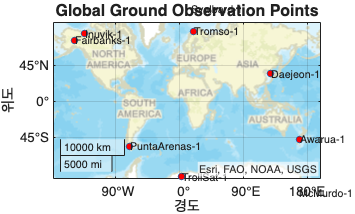

gt = groundTrack(sat, "LeadLineColor",[0.6, 0.6, 0.6],"TrailLineColor",[0.6, 0.6, 0.6]);

for gs_index = 1:N
gs_name = string(GS_Data{gs_index,1});
gs = groundStation(sc, lats(gs_index), lons(gs_index), ...
    "Name", gs_name,'MaskElevationAngle',Min_Elevation_angle);
end

GS = sc.GroundStations;

set(GS,'ShowLabel',1)
set(GS,'MarkerSize',20)
set(GS,'MarkerColor','m')
set(GS(2),'MarkerColor','g')

figure;
geoplot(lats, lons, ...
    'Marker','o', ...
    'LineStyle','none', ...
    'MarkerSize',5, ...
    'MarkerFaceColor','r','DisplayName','true')

geobasemap streets

title('Global Ground Observation Points', ...
    'FontSize',12, ...
    'FontWeight','bold')

for k = 1:N
    text(lats(k), lons(k)+1, cityNames(k),'FontSize',8)
end



satelliteScenarioViewer(sc,'Dimension','3D');

play(sc)

% SAT_GS_access_sequence = [];
%  for Payload_index = 1:length(Payload_list)
%      % EOIR_payload_index % 계산속도 체크용
%      SAT_GS_access_sequence = [SAT_GS_access_sequence,access(gs, Payload_list(Payload_index))];
%  end    
% 
% SAT_GS_access_interval = accessIntervals(SAT_GS_access_sequence);
% filename = ['Scenario_' num2str(number_of_satellites) '_SATs_' num2str(number_of_orbit_planes) '_Orbit_Planes_' num2str(inclination_angle) '_inc_' num2str(sim_duration) 'days_access_interval'];
% fullname = fullfile(savepath,filename);
% save(fullname,'SAT_GS_access_interval')
% 
% % CSV 파일로도 저장
% csv_fullname = [fullname, '.csv'];
% writetable(SAT_GS_access_interval, csv_fullname);